# **Brief study Dow Jones 3D investing based on SDG Score by Robeco**

**Robeco SDG link = *****https://www.robeco.com/en-int/sustainable-investing/how-do-companies-and-countries-score-on-sustainability***

## **Data import**

data = readtable("DowJones.xlsx", VariableNamingRule="preserve");
price = readtable("DowJones.xlsx", Sheet="Price", VariableNamingRule="preserve");

## **Are SDG related to the Sector, Market Capitalization and P/E Ratio?**

## **Sector:**

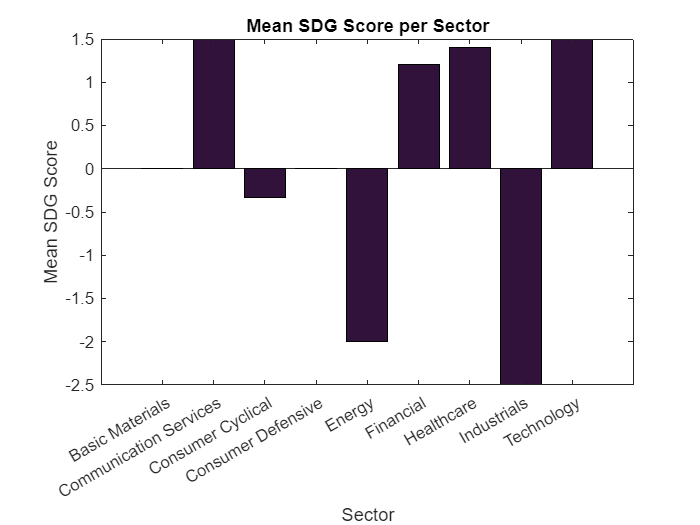

% Extract relevant columns
sector = data.Sector;
robecoSDG = data.RobecoSDG;

% Convert 'Sector' to a categorical variable
sector = categorical(sector);

% Group the data by sector and calculate mean Robeco SDG score
[mean_scores, sector_names] = grpstats(robecoSDG, sector, {'mean', 'gname'});

% Plot the bar graph
bar(mean_scores)
xticks(1:numel(sector_names))
xticklabels(cellstr(sector_names))
xlabel('Sector')
ylabel('Mean SDG Score')
title('Mean SDG Score per Sector')

#### **On the overall Market Cap**

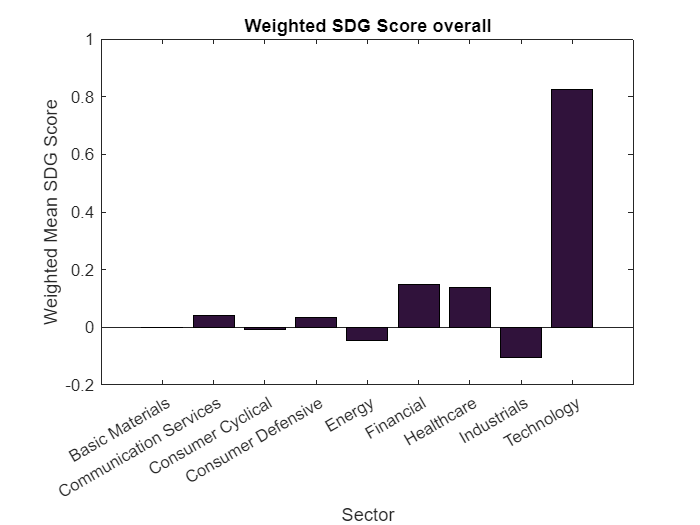

total_mkt_cap = sum(data.MarketCap);
mktCap = data.MarketCap;
groups = findgroups(sector);
% Calculate the overall weighted average
weighted_overall = splitapply(@(mktCap, robecoSDG) sum(mktCap .* robecoSDG) / total_mkt_cap, mktCap, robecoSDG, groups);

unique_sectors = categories(sector);

% Plot the bar graph
bar(weighted_overall)
xticks(1:numel(unique_sectors))
xticklabels(cellstr(unique_sectors))
xlabel('Sector')
ylabel('Weighted Mean SDG Score')
title('Weighted SDG Score overall')

## **EPS:**

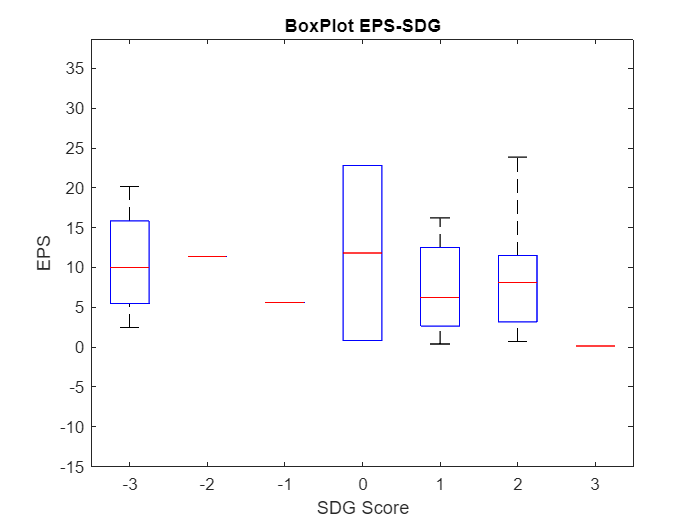

pe = data.PE;
last_price = price(end,2:end);
eps = table2array(last_price)' ./ pe;

%boxplot
boxplot(eps, robecoSDG)
ylabel('EPS')
xlabel('SDG Score')
title('BoxPlot EPS-SDG')

## Portfolio Optimization

**Asset returns, covariance and correlation**

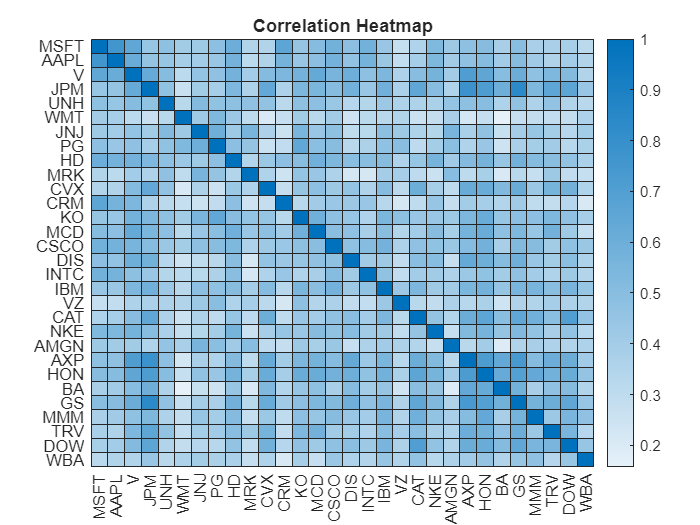

returns = tick2ret(price(:,2:end));
returns = table2array(returns);
correlation = corrcoef(returns);
asset_covariance = cov(returns);
asset = price(:,2:end).Properties.VariableNames;
%correlation heatmap
heatmap(asset, asset,correlation)
title("Correlation Heatmap")

### **Mean-Variance-Sustainability optimization**

As first, let's see how the sustainability behaves in the classical Mean-Variance approach

                                                                
$$\min_{w} \quad w^T\Sigma w \\
\textrm{s.t.}
 \quad w^T\mathbf{1} = 1 \\
\quad \quad w \geq 0 \\
\quad \quad w \leq 0.1\\
\quad \quad w^T\mu \geq \mathbb{E} 
$$


First, let's define a linear space of desidered returns

mean_returns = mean(returns);
n_ptf = 100;
exp_ret = linspace(min(mean_returns), max(mean_returns), n_ptf);

all_w = zeros(n_ptf, 30);

Now let's optimize the problem above

for i = 1:n_ptf
    % define Weights variable
    w = optimvar('w', 30, 'LowerBound',0, 'UpperBound',0.1);
    
    % define objective funtion
    obj = w' * asset_covariance * w;
    prob = optimproblem('Objective',obj);
    prob.Constraints.sumw = sum(w) == 1;
    prob.Constraints.ret = mean_returns * w >= exp_ret(i);
    
    sol = solve(prob);
    % store the solution in all_w
    all_w(i,:) = sol.w;
end

Solving problem using quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Solving problem using quadprog.

Minimum found th

#### **Compute portfolio metrics**

ptf_ret = (all_w * mean_returns') .* 252;
ptf_SDG = all_w * robecoSDG;

ptf_std = zeros(n_ptf, 1);
for i = 1:n_ptf
    ptf_std(i) = sqrt(all_w(i, :) * asset_covariance * all_w(i, :)') * sqrt(252);
end

#### **Graph of the combination**

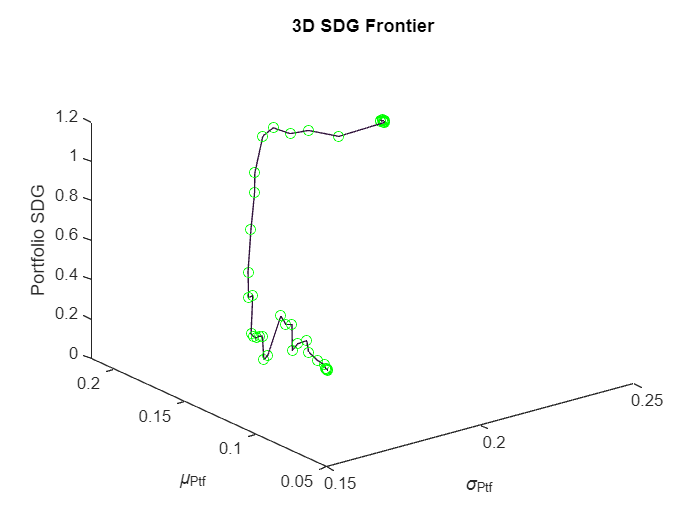

plot3(ptf_std, ptf_ret, ptf_SDG)
xlabel('\sigma_{Ptf}')
ylabel('\mu_{Ptf}')
zlabel('Portfolio SDG')
title('3D SDG Frontier')
hold on
scatter3(ptf_std, ptf_ret, ptf_SDG, 'green')
hold off

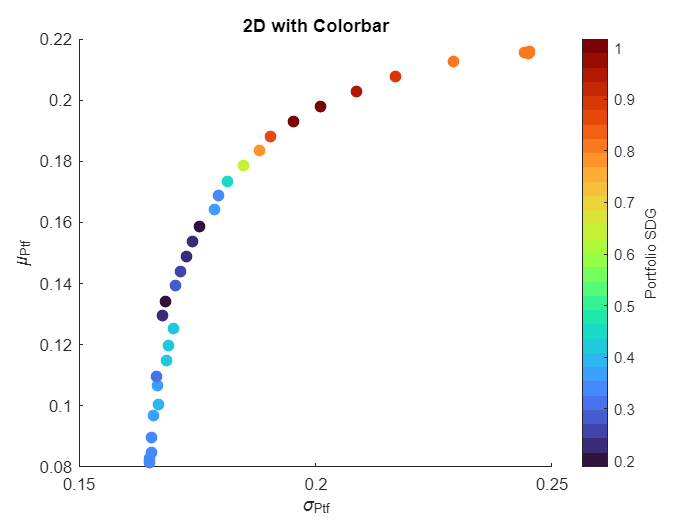


% Create the scatter plot
scatter(ptf_std, ptf_ret, 50, ptf_SDG, 'filled');
xlabel('\sigma_{Ptf}');
ylabel('\mu_{Ptf}');
title('2D with Colorbar');
% Add color bar
colorbar;
ylabel(colorbar, 'Portfolio SDG');

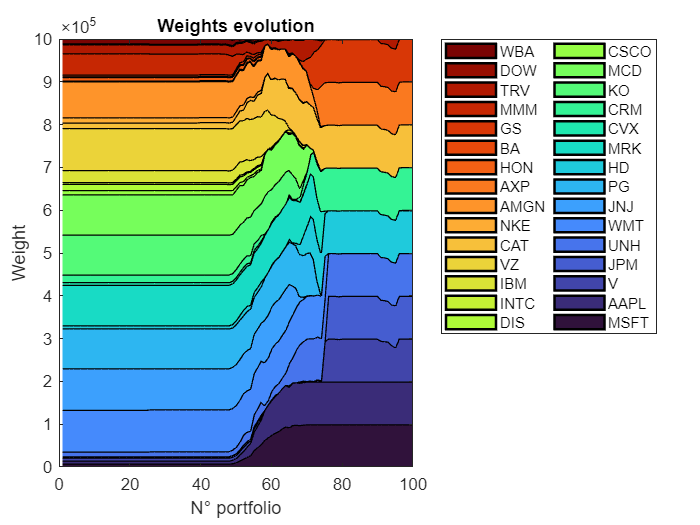


area(round(all_w, 3) .* 1000000, 'LineWidth', 1.5)
colororder(colormap(turbo(30)))
legend(asset, 'Location','bestoutside', 'NumColumns',2)
ylim([0,1000000])
ylabel('Weight')
xlabel('N° portfolio')
title('Weights evolution')
grid on;

### **Optimization with variance penalty and sustainability premium**

Let's introduce a new formulation for the optimization problem, where the objective function tries to maximize the portfolio's returns with a penalty for the variance and sustinability premium

                                                        
$$\max_{w, \lambda, \gamma} w^T\mu - \lambda (w^T\Sigma w)+\gamma(w^TSDG)\\
s.t. \quad w^T\mathbb{1} = 1\\
\quad \quad w \geq 0\\
\quad \quad w\leq 0.1\\
\quad \quad w^T\mu \geq \mathbb{E}\\
\quad \quad \gamma \geq \lambda 
\quad \quad \gamma, \lambda \in [0,1]$$


the last two constraints state that we have a preferencies for sustainability

all_w_2 = zeros(n_ptf, 30);
coeff = zeros(n_ptf, 2);
initial_point.w_2 = ones(30,1) / 30;
initial_point.lambda = 0.02;
initial_point.gamma = 0.03;
for i = 1:n_ptf
    w_2 = optimvar('w_2', 30, 'LowerBound',0, 'UpperBound',0.1);
    lambda = optimvar('lambda', 'LowerBound', 0, 'UpperBound', 1, 'Type', 'continuous');
    gamma = optimvar('gamma', 'LowerBound', 0, 'UpperBound', 1, 'Type', 'continuous');

    obj_2 = - (mean_returns * w_2 - lambda * (w_2' * asset_covariance * w_2) + gamma * (robecoSDG' * w_2));
    
    prob_2 = optimproblem('Objective',obj_2);
    prob_2.Constraints.sumw2 = sum(w_2) == 1;
    prob_2.Constraints.ret = mean_returns * w_2 >= exp_ret(i);
    prob_2.Constraints.coef = gamma >= lambda;

    sol_2 = solve(prob_2, initial_point);
    % store the solution in all_w
    all_w_2(i,:) = sol_2.w_2;
    coeff(i,1) = sol_2.lambda;
    coeff(i,2) = sol_2.gamma;
end

Solving problem using fmincon.

Feasible point with lower objective function value found.


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


#### **Compute new portfolio metrics**

ptf_ret_2 = (all_w_2 * mean_returns') .* 252;
ptf_SDG_2 = all_w_2 * robecoSDG;

ptf_std_2 = zeros(n_ptf, 1);
for i = 1:n_ptf
    ptf_std_2(i) = sqrt(all_w_2(i, :) * asset_covariance * all_w_2(i, :)') * sqrt(252);
end

#### **Graph of the combination**

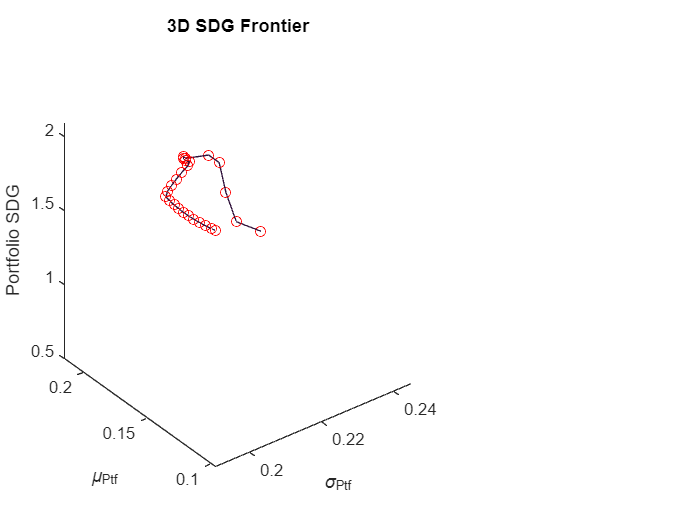

plot3(ptf_std_2, ptf_ret_2, ptf_SDG_2)
xlabel('\sigma_{Ptf}')
ylabel('\mu_{Ptf}')
zlabel('Portfolio SDG')
title('3D SDG Frontier')
hold on
scatter3(ptf_std_2, ptf_ret_2, ptf_SDG_2, 'r')
hold off

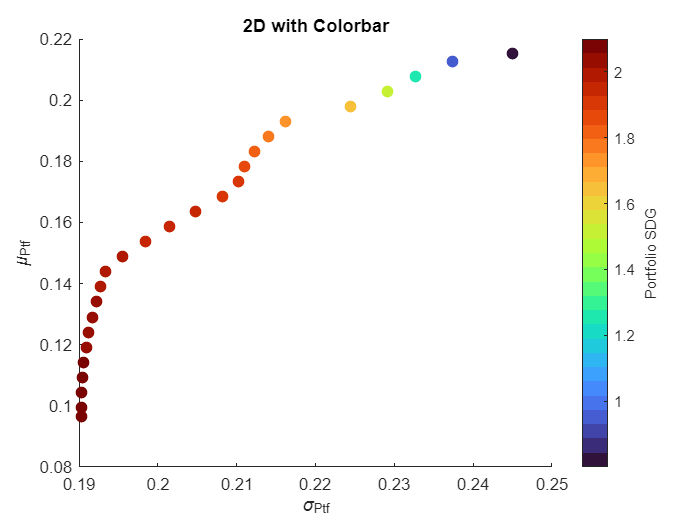


% Create the scatter plot
scatter(ptf_std_2, ptf_ret_2, 50, ptf_SDG_2, 'filled');
xlabel('\sigma_{Ptf}');
ylabel('\mu_{Ptf}');
title('2D with Colorbar');
% Add color bar
colorbar;
ylabel(colorbar, 'Portfolio SDG');

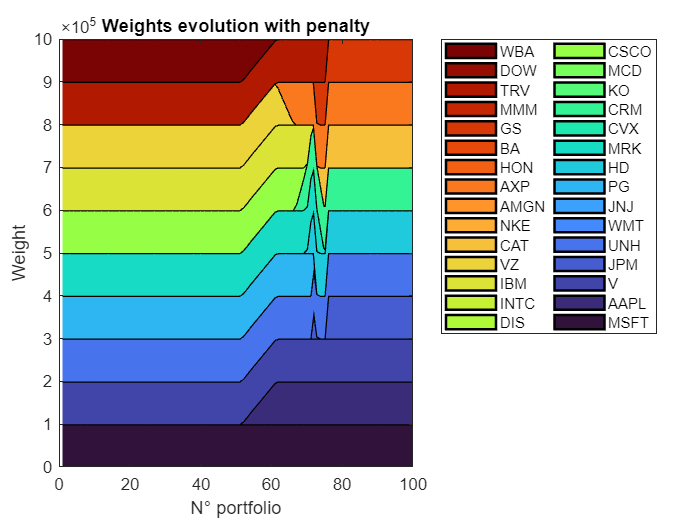

area(round(all_w_2, 3) .* 1000000, 'LineWidth', 1.5)
colororder(colormap(turbo(30)))
legend(asset, 'Location','bestoutside', 'NumColumns',2)
ylim([0,1000000])
ylabel('Weight')
xlabel('N° portfolio')
title('Weights evolution with penalty')
grid on;

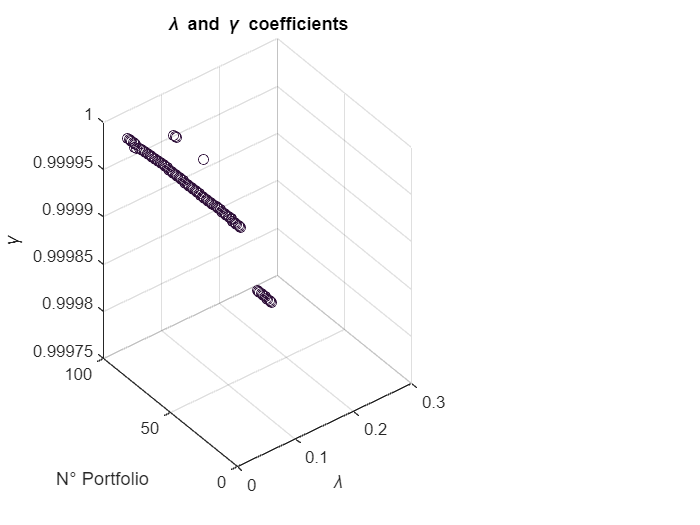


%scatter plot of gamma and lambda
scatter3(coeff(:,1), linspace(1, n_ptf,n_ptf), coeff(:,2))
title('\lambda and \gamma coefficients')
xlabel('\lambda')
ylabel('N° Portfolio')
zlabel('\gamma')